# Lysosome Display

This live script was used to generate the figures of taste cells with their lysosome 

NOTE: The tables used in this script are generated and/or updated in the companion [**lysosome_get_tables**](matlab:open('./lysosome_get_tables.mlx')) live script

**Additional Requirements:**

- The MatGeom toolbox:  [https://github.com/mattools/matGeom](https://github.com/mattools/matGeom) 

## Initialize functions and load data

setupMatGeom % MatGeom needs to be installed

Installing MatGeom Library
Adding module: geom2d               (ok)
Adding module: polygons2d           (ok)
Adding module: graphs               (ok)
Adding module: polynomialCurves2d   (ok)
Adding module: geom3d               (ok)
Adding module: meshes3d             (ok)
Adding module: utils                (ok)


close all
clearvars
project_folder = "Dying_Taste_Cell_analysis";

addpath(fullfile(project_folder,"tastebud_toolbox"),...
    fullfile(project_folder,"tastebud_toolbox","colornames"))

if exist(fullfile(project_folder,"lysosomesVL.mat"),"file")
    load(fullfile(project_folder,"lysosomesVL.mat")) % load VL
    load(fullfile(project_folder,'cellT.mat')) %cellT
    load(fullfile(project_folder,"lysT.mat")) %lysT
    idT = VL.Properties.UserData.idT;
end

 cellT.Polarity = get_polarity(cellT.CellID)

# Display

### Plot Two cells

- TB1_AP13_EM

- TB1_AP14_EM

mmFigure;
coi = ["TB1_AP13_EM" "TB1_AP14_EM"]; % cells of interest
la = ismember(cellT.Object,coi);
row = find(la);
hp = plot_cells(VL, cellT(row,:),'alphaShape',false);

1. TB1_AP13_EM
2. TB1_AP14_EM


exportgraphics(gcf,fullfile(project_folder,"Figures","AP13vAP14.png"),Resolution=300)

## Plot tiled

#### Plot cells as alpha shapes

figure(Visible="on")
ax = plot_tiled(VL,cellT); 

# Local Functions

back to analysis

## plot_cells

just the cells

Rendering...
1. TB1_IMMCell09_CM_ry
2. TB1_IMMcell08_CM_RKJ
3. TB2 Nucleus_26_cw_IV-ry
4. TB2_T4C-01_cw
5. TB1_AP31_EM
6. TB2_t3cell02_CM_RSL
7. TB2_T3C-08_cw
8. TB2_T3C-17_cw
9. TB2_T3C-14_FR
10. TB2_T3Cell07_cm_RSL
11. TB1_AP02_EM
12. TB2_T2C-12_cw
13. TB2_T2C-09_cw
14. TB1_AP14_EM
15. TB2_T2Cell03_CM_LES
16. TB2_T2C-10_cw
17. TB1_AP38_EM
18. TB1_AP34_EM
19. TB1_AP36_EM
20. TB2 Nucleus_04_cw_cell-ry
21. TB1_AP16_EM
22. TB1_AP37_EM
23. TB1_AP70_RSL
24. TB2_T1C-05_cw
25. TB2_T1C-06_cw
26. TB2_TCdying-02_cw
27. TB2_TCdying-01_cw
28. TB1_AP44_EM
29. TB1_AP51_EM
30. TB1_AP13_EM
31. TB2_T2C-03_cw
32. TB1_AP40_EM
33. TB2_T2C-01_FR


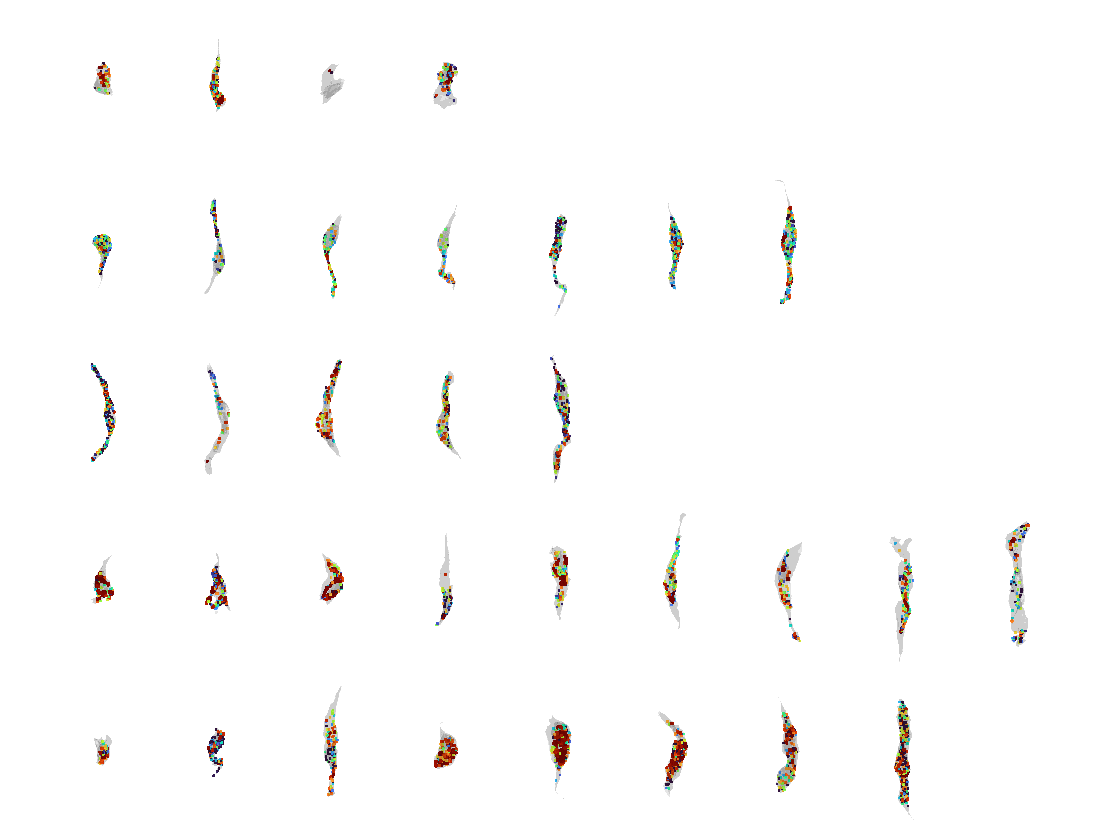

function hp = plot_cells(VL, cellT,cell_render_method, new_fig)


arguments
    VL table
    cellT table
    cell_render_method char = 'alphaShape';
    new_fig logical = true;
end

if new_fig
    figure(Visible="on",Color="white");
    tiledlayout("flow",TileSpacing="none",Padding="tight")
end

% fcolor = 'k';
% falpha = 0.1;

hp = gobjects(height(cellT),1);
cm = turbo(max(VL.SizeLabel));


for n=1:height(cellT)

    object = cellT.Object(n);
    polarity = cellT.Polarity(n);
    nexttile
    hp(n) = plot_cell_lys_overlay(VL,object,polarity,cell_render_method);
    % title(sprintf('%d. %s',n,object))

    fprintf('%d. %s\n',n,object)
    colormap(cm);


end
end

### plot_tiled

function ax = plot_tiled(VL, cellT, options)

arguments
    VL table
    cellT table
    options.plotFast logical = true
    options.darkTheme char = 'off'
end

switch options.darkTheme
    case 'on'
        fcolor='w';
        falpha=0.2;
        figColor = 'k';
    case 'off'
        fcolor='k';
        falpha=0.1;
        figColor = 'w';
end

cellT = sortrows(cellT,["PlotSort","SurfaceArea"]);
cN=histcounts(cellT.PlotSort,categories(cellT.PlotSort)); 
total = height(cellT);
rows = numel(categories(cellT.PlotSort));
cols = max(cN);

% create tiling indexing to sort cell type by row
tile_idx = NaN(1,total);
last_idx = 0;
for ti = 1:rows
    tile_idx(last_idx+1:last_idx+cN(ti)) = (1:(cN(ti)))+cols*(ti-1);
    last_idx = last_idx+cN(ti);
end

% idT = VL.Properties.UserData.idT;

% prepare to plot
figure(Visible="on");
tiledlayout(rows,cols,TileSpacing="none",Padding="tight");
ax = gobjects(total,1);
cm = turbo(max(VL.SizeLabel));

% wb = waitbar(0,'Rendering...');
fprintf('Rendering...\n')

for n=1:total
        
    [vCell, vLys, szLys] = getVertsFromCellID(VL, cellT.Object(n),cellT.Polarity(n)); % align point clouds to axes

    % plot surfaces
    ax(n) = nexttile(tile_idx(n));

    % PC = pointCloud(vLys); % healthy lysosomes
    pcshow(vLys, szLys,AxesVisibility="off");

    hold on

    if options.plotFast
        plot_alphaShape(vCell, cellT.Object(n),fcolor, falpha);
    else
        plot_patch(vCell,cellT.Object(n),fcolor,falpha);
    end
  
    xlim([-7 7])
    ylim([-5 5])
    zlim([-45 45])

    set(gca,CameraTarget=[0,0,0])

    colormap(cm);

    fprintf('%d. %s\n',n,cellT.Object(n))
    % waitbar(n/total,wb,sprintf('%d. %s',n,cellT.Object(n)))
end
set(gcf,Color=figColor)
end


overlay cell and lysosome


function hp = plot_cell_lys_overlay(VL,object,polarity,cell_render_method)

[vCell, vLys, szLys] = getVertsFromCellID(VL, object,polarity); % align point clouds to axes

% PC = pointCloud(vLys); % healthy lysosomes
pcshow(vLys, szLys,AxesVisibility="off");
hold on

fcolor = 'k';
falpha = 0.1;
switch cell_render_method
    case 'alphaShape'
        hp = plot_alphaShape(vCell, object,fcolor, falpha);
    case 'PointCloud'
        % pc = pointCloud(vCell);
        hp = pcshow(vCell);
    case 'patch'
        hp = plot_patch(vCell, object,fcolor, falpha);
        axis equal
end

xlim([-7 7])
ylim([-5 5])
zlim([-45 45])

set(gca,CameraTarget=[0,0,0])

axis off

set(gcf,Color='w')
end

### getVertsFromCellID

function [vCell,vLys, szLys] = getVertsFromCellID(VL,CellID,polarity) 

idT = VL.Properties.UserData.idT;

% get vertices
object = idT.Lysosome(idT.Cell == CellID);
la = VL.Object == object;
vLys = (VL{la,["x" "y" "z"]});
szLys = VL.SizeLabel(la);

object = idT.Cell(idT.Cell == CellID);
vCell = (VL{VL.Object == object,["x" "y" "z"]});

% transform vertices
vLys = vLys - mean(vCell); % center to 0,0,0
vCell = vCell - mean(vCell);

[~,~,V]=svd(vCell,0); % Find the direction of most variance
vCell =  vCell * V;
vLys = vLys * V;

% align to z-axis
angl = 90 * polarity;
vCell = mmRotateSurfaceVertices(vCell,'y',angl);
vLys = mmRotateSurfaceVertices(vLys,'y',angl);

% rotate around z-axis
vCell = mmRotateSurfaceVertices(vCell,'z',90);
vLys = mmRotateSurfaceVertices(vLys,'z',90);
   
end

### plot_alphaShape

function hp = plot_alphaShape(verts, tag,fcolor, falpha)
    shp = alphaShape(verts,1);
    hp = plot(shp, ...
        Tag=tag,...
        FaceColor=fcolor, ...
        FaceAlpha=falpha, ...
        EdgeColor='none');
end

### plot_patch

create surface mesh from point clouds and plot. Called here

function hp = plot_patch(verts, tag,fcolor, falpha)

arguments
    verts (:,3) double
    tag char
    fcolor = 'k'
    falpha (1,1) double = 0.1
end

PC = pointCloud(verts);
% SM = pc2surfacemesh(PC,"ball-pivot",[50,50,70]);
[SM, ~] = pc2surfacemesh(PC,"ball-pivot");
removeDefects(SM,"nonmanifold-edges")
removeDefects(SM,"degenerate-faces")
removeDefects(SM,"unreferenced-vertices")
removeDefects(SM,"duplicate-vertices")
removeDefects(SM,"duplicate-faces")

hp = patch(Faces=SM.Faces, ...
    Vertices=SM.Vertices, ...
    FaceColor=fcolor, ...
    FaceAlpha=falpha, ...
    EdgeColor='none', ...
    Tag=tag);

end

## discontinued

### plot same axes

function plot_grouped(VL,Structure)
%PLOT_SAME_AXIS
% INPUTS:
%   - VL (table): Vertices table
%   - Structure (char): cell or lysosome
%   - lysT (table): optional. Lysosome Table

arguments
    VL table
    Structure char
end

idT = VL.Properties.UserData.idT;
laS = idT.Structure==Structure;
grps = findgroups(idT.TasteBud, idT.Dataset);

figure(Visible="on",WindowStyle="docked")

cm = turbo(max(VL.SizeLabel));


for g=unique(grps)'

    objects = idT.Object(laS & g==grps);

    nexttile
    for n=1:numel(objects)
        la = VL.Object == objects(n); % 
        PC = pointCloud(VL{la,["x" "y" "z"]}); % 

        if strcmp(Structure,'lysosome')
            colormap(cm)
            labels = VL.SizeLabel(la);
        else
            labels = repmat(n,PC.Count,1);
        end
        pcshow(PC.Location,labels);
        hold on
    end

    xlabel('x'), ylabel('y'), zlabel('z')
    axis off

%     legend(objects,Interpreter="none",Color='w')
    
end
colorbar
end

### plot_cell_lys 

function plot_same_ax(VL,cellT,xi, zi, do_face_color,plot_fast)
%PLOT_CELL_LYS. Overlay cell and lys in the same axis. Align each cell to the z-axis and space out along the x-axis
% INPUTS
%   - VL
%   - cell_idx (vector, scalar): indices of the Lysomes in idT. Must be
%                                   even numbers
%   - polarity: changes direction of cell (up or down)
%   - plot_fast: use alpha_shape to quickly plot the cell

arguments
    VL table
    cellT table
    xi double
    zi double = 0
    do_face_color logical = false
    plot_fast logical = true
end

figure(Visible="on")
colormap(turbo(max(VL.SizeLabel)));
idT = VL.Properties.UserData.idT;

% cellT= sortrows(cellT,["PlotSort","Volume"]);

cellT.XSpacing = zeros(height(cellT),1);
cellT.ZSpacing = zeros(height(cellT),1);

if zi
    cats = categories(cellT.PlotSort);
    for n=1:numel(cats)
        la = cellT.PlotSort==cats{n};
        cellT.XSpacing(la) = 0:xi:xi*(sum(la)-1);
        cellT.ZSpacing(la) = zi*(n-1);
    end
else % just line em up
    cellT.XSpacing = (0:xi:xi*(height(cellT)-1))';
end

for n=1:height(cellT)
   
    % get vertices
    [vCell, vLys, szLys] = getVertsFromCellID(VL, cellT.CellID(n),cellT.Polarity(n)); % align point cloud to axes

    % evenly distribute surfaces across the axis
    vCell(:,[1 3]) = vCell(:,[1 3]) + [cellT.XSpacing(n) cellT.ZSpacing(n)];
    vLys(:,[1 3]) = vLys(:,[1 3]) + [cellT.XSpacing(n) cellT.ZSpacing(n)];

    % plot surfaces
    PC = pointCloud(vLys); % healthy lysosomes
    pcshow(PC.Location, szLys,AxesVisibility="off");

    hold on

    if do_face_color
        cfc = idT.CellColor(la); % cell face color
    else
        cfc = 'k';
    end

    if plot_fast
        shp = alphaShape(vCell);
        plot(shp,FaceColor=cfc,FaceAlpha=0.1,EdgeColor='none',Tag=cellT.Object(n));
    else
        plot_patch(vCell)
    end

    title(idT.Type(n),Color='k')
    xlabel('x'), ylabel('y'), zlabel('z')

    %     xlim([2500 6000]); ylim([1400 11000]); zlim([0 3800])
    %     view(55,-70)
end
% colorbar
set(gcf,"Color","w")
end

### plot exploded cells

By explode, I mean separated cells. We use multiplication to separate the centroids

function plot_cell_lys_explode(VL,cell_idx,explode_factor)
%PLOT_CELL_LYS_EXPLODE. Overlay cell and lys in the same axis. Recenter the
% cells to 0,0,0. Spread out cells using multiplicaation of centroids
% INPUTS
%   - VL
%   - cell_idx (vector, scalar): indices of the Lysomes in idT. Must be
%        even numbers.
%   - explode_factor(scalar): multiplication factor that determines by how
%        much to separate the surfaces. 0 means no separate

figure(Visible="on")
idT = VL.Properties.UserData.idT;

objects =  [idT.Object(cell_idx); idT.Object(cell_idx-1)];
la = ismember(VL.Object,objects);

center_all = mean(VL{la,["x" "y" "z"]}); % the center of all cells

for n=1:numel(cell_idx)
    %     nexttile
    ci = cell_idx(n);

    % get vertices
    la = VL.Object == idT.Object(ci); % get lys
    v_lys = (VL{la,["x" "y" "z"]});
    SzLabel = VL.SizeLabel(la);

    la = VL.Object == idT.Object(ci-1); % get cell
    v_cell = VL{la,["x","y","z"]};

    % transform vertices
    v_lys = v_lys - mean(center_all); % center all cells to 0,0,0
    v_cell = v_cell - mean(center_all);

    v_lys = v_lys + mean(v_cell)*explode_factor; % explode - separate cells
    v_cell = v_cell + mean(v_cell)*explode_factor;
      
    PC = pointCloud(v_lys); % healthy lysosomes
    pcshow(PC.Location, SzLabel,AxesVisibility="off");

    hold on
    shp = alphaShape(v_cell);
    plot(shp,FaceColor='k',FaceAlpha=0.1,EdgeColor='none');

    title(idT.Type(n),Color='k')
    xlabel('x'), ylabel('y'), zlabel('z')

    %     xlim([2500 6000]); ylim([1400 11000]); zlim([0 3800])
    %     view(55,-70)
end
% colorbar
set(gcf,"Color","w")
end